**Importing the datasets downloaded from IEEE dataport.**

active_eeg = readtable('ActiveEEGpaper.csv'); 
drowsy_eeg = readtable('InactiveEEGpaper.csv');

**Extracting just the voltage values from the file, ignoring the timestamps. Column 2 --> voltage values**

active_raw = active_eeg.Var2;
drowsy_raw = drowsy_eeg.Var2;

**Applying notch and bandpass filters**

fs = 256;
[notch_2,notch_1] = iirnotch(50/(fs/2), 50/(35*fs/2));
[band_2,band_1] = butter(4, [0.5 30]/(fs/2), 'bandpass');

filtered_eeg = @(sig) filtfilt(band_2, band_1, filtfilt(notch_2, notch_1, sig));

active_filtered = filtered_eeg(active_raw);
drowsy_filtered = filtered_eeg(drowsy_raw);

**Splitting the data before segmentation**

**80% --> Training data**

**20% --> Testing dataA**

holdoutRatio = 0.2;

active_split_index = floor(length(active_filtered) * (1 - holdoutRatio));
drowsy_split_index= floor(length(drowsy_filtered) * (1 - holdoutRatio));

active_train = active_filtered(1:active_split_index);
active_test_segments  = active_filtered(active_split_index+1:end);

drowsy_train = drowsy_filtered(1:drowsy_split_index);
drowsy_test  = drowsy_filtered(drowsy_split_index+1:end);

**Segmentation of the signal using 3s windows.**

window_size = 3;
window_length = fs * window_size;

segmented_signal = @(signal) reshape( ...
    signal(1:floor(length(signal)/window_length)*window_length), ...
    window_length, [] ...
);
active_train_segments = segmented_signal(active_train);
active_test_segments = segmented_signal(active_test_segments);

drowsy_train_segments = segmented_signal(drowsy_train);
drowsy_test_segments  = segmented_signal(drowsy_test);

**Function to extract features.**

function features = computeEEGFeatures(segments, fs)
    numSeg = size(segments,2);
    features = zeros(numSeg, 12); 

    for i = 1:numSeg
        sig = segments(:,i);
        
        [pxx,f] = pwelch(sig,[],[],[],fs);

        delta = bandpower(pxx,f,[0.5 4], 'psd');
        theta = bandpower(pxx,f,[4 8], 'psd');
        alpha = bandpower(pxx,f,[8 13], 'psd');
        beta  = bandpower(pxx,f,[13 30], 'psd');
        total_power = bandpower(pxx,f,[0.5 30], 'psd');

        rel_delta = delta / total_power;
        rel_theta = theta / total_power;
        rel_alpha = alpha / total_power;
        rel_beta  = beta  / total_power;

        alpha_beta_ratio = alpha / beta;

        p_norm = pxx / sum(pxx);
        spectral_entropy = -sum(p_norm .* log2(p_norm + eps));

        activity = var(sig);
        mobility = sqrt(var(diff(sig)) / activity);
        complexity = sqrt(var(diff(diff(sig))) / var(diff(sig))) / mobility;

        features(i,:) = [
            delta, theta, alpha, beta, alpha_beta_ratio, ...
            rel_delta, rel_theta, rel_alpha, rel_beta, ...
            spectral_entropy, mobility, complexity
        ];
    end
end

activeTrainFeat = computeEEGFeatures(active_train_segments, fs);
activeTestFeat  = computeEEGFeatures(active_test_segments, fs);

drowsyTrainFeat = computeEEGFeatures(drowsy_train_segments, fs);
drowsyTestFeat  = computeEEGFeatures(drowsy_test_segments, fs);

**Combining the active and inactive sets into single features and labels variable.**

trainFeatures = [activeTrainFeat; drowsyTrainFeat];
trainLabels   = [ones(size(activeTrainFeat,1),1); zeros(size(drowsyTrainFeat,1),1)];

testFeatures  = [activeTestFeat; drowsyTestFeat];
testLabels    = [ones(size(activeTestFeat,1),1); zeros(size(drowsyTestFeat,1),1)];

**Training the SVM model.**

model = fitcsvm(trainFeatures, trainLabels, ...
    'KernelFunction', 'rbf', 'Standardize', true, ...
    'OptimizeHyperparameters', 'auto', ...
    'HyperparameterOptimizationOptions', struct('AcquisitionFunctionName', ...
    'expected-improvement-plus', ...
    'ShowPlots', false, ...
    'Verbose',0 ...
    ));

**Evaluating the Model by using Test data.**

predictedLabels = predict(model, testFeatures);
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
fprintf('Accuracy (Leakage-Free): %.2f%%\n', accuracy * 100);

Accuracy (Leakage-Free): 96.23%


**Displaying the confusion matrix**

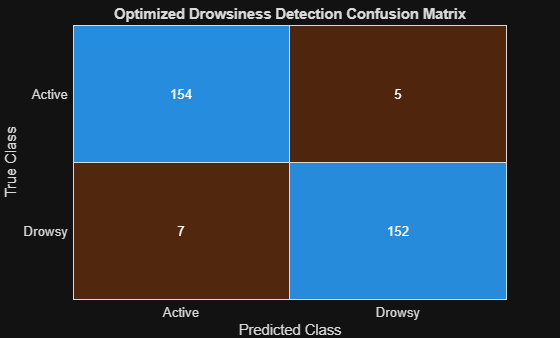

confMat = confusionmat(testLabels, predictedLabels);
c = confusionchart(confMat, {'Drowsy', 'Active'}, ...
    'Title', 'Optimized Drowsiness Detection Confusion Matrix');